data=readmatrix('C:/Users/Dell/Downloads/Shear_Modulus.csv');
data1=readmatrix('C:/Users/Dell/Downloads/shear1.csv');
data2=readmatrix('C:/Users/Dell/Downloads/shear2.csv');
data3=readmatrix('C:/Users/Dell/Downloads/shear3.csv');
data4=readmatrix('C:/Users/Dell/Downloads/shear4.csv');
data5=readmatrix('C:/Users/Dell/Downloads/shear5.csv');
data6=readmatrix('C:/Users/Dell/Downloads/shear6.csv');
x=data(:,1:6);
y=data(:,7);
%m=length(y);
x1=data1(:,2:7);
x2=data2(:,1:6);
x3=data3(:,1:6);
x4=data4(:,1:6);
x5=data5(:,1:6);
x6=data6(:,1:6);

Visualization of the data

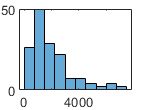

histogram(y,10);

Normalize the features

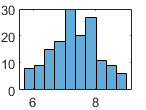

 y2=log(1+y);
 for i=1:6
     x2(:,i)=(x(:,i)-min(x(:,i)))/max(x(:,i))-min(x(:,i));
 end
 for i=1:6
     x21(:,i)=(x1(:,i)-min(x1(:,i)))/max(x1(:,i))-min(x1(:,i));
 end
 for i=1:6
     x22(:,i)=(x2(:,i)-min(x2(:,i)))/max(x2(:,i))-min(x2(:,i));
 end
 for i=1:6
     x23(:,i)=(x3(:,i)-min(x3(:,i)))/max(x3(:,i))-min(x3(:,i));
 end
 for i=1:6
     x24(:,i)=(x4(:,i)-min(x4(:,i)))/max(x4(:,i))-min(x4(:,i));
 end
 for i=1:6
     x25(:,i)=(x5(:,i)-min(x5(:,i)))/max(x5(:,i))-min(x5(:,i));
 end
 for i=1:6
     x26(:,i)=(x6(:,i)-min(x6(:,i)))/max(x6(:,i))-min(x6(:,i));
 end
 histogram(y2,10);

Training an ANN model

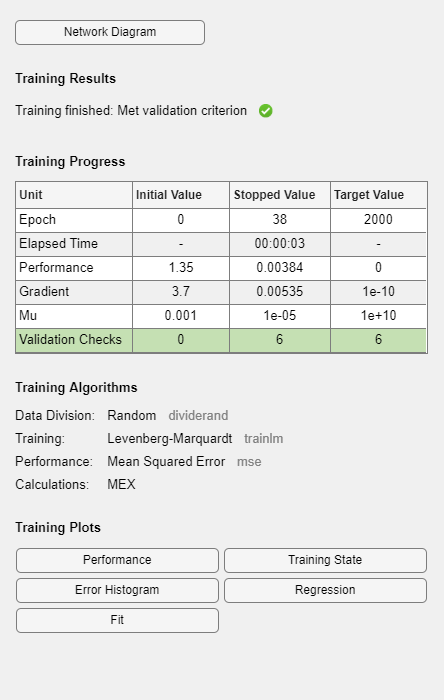

xt=x2';
yt=y2';
xt1=x21';
xt2=x22';
xt3=x23';
xt4=x24';
xt5=x25';
xt6=x26';
hiddenLayerSize=6;
net=fitnet(hiddenLayerSize);
%layer=sigmoidLayer('Name','sig1')
%net.layers{1}.transferFcn = 'poslin';
%net.layers{2}.transferFcn = 'purelin';

net.divideParam.trainRatio=70/100;
net.divideParam.valRatio=30/100;
net.divideParam.testRatio=0/100;
net.trainParam.epochs=2000;
net.trainParam.min_grad=1e-10;
[net,tr]=train(net,xt,yt);

save net.mat;

Performance of the ANN network

yTrain=exp(net(xt(:,tr.trainInd)))-1;
yTrainTrue=exp(yt(tr.trainInd))-1;
sqrt(mean((yTrain-yTrainTrue).^2))

ans = 164.8687

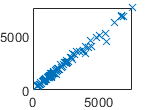

%m=median(yTrain,'all')
%m1=mean(yTrain-m)
%res=(m1/m)*100
plot(yTrainTrue,yTrain,'x')

MAPE= mean((abs(yTrain-yTrainTrue))/yTrainTrue)*100;
predict1=exp(net(xt1(:,tr.trainInd)))-1;
MAPE1= mean((abs(predict1-yTrainTrue))/yTrainTrue)*100

MAPE1 = 5.3317

predict2=exp(net(xt2(:,tr.trainInd)))-1;
MAPE2= mean((abs(predict2-yTrainTrue))/yTrainTrue)*100

MAPE2 = 678.2122

predict3=exp(net(xt3(:,tr.trainInd)))-1;
MAPE3= mean((abs(predict3-yTrainTrue))/yTrainTrue)*100

MAPE3 = 4.2083

predict4=exp(net(xt4(:,tr.trainInd)))-1;
MAPE4= mean((abs(predict4-yTrainTrue))/yTrainTrue)*100

MAPE4 = 46.7832

predict5=exp(net(xt5(:,tr.trainInd)))-1;
MAPE5= mean((abs(predict5-yTrainTrue))/yTrainTrue)*100

MAPE5 = 74.2564

predict6=exp(net(xt6(:,tr.trainInd)))-1;
MAPE6= mean((abs(predict6-yTrainTrue))/yTrainTrue)*100

MAPE6 = 4.8502